% Carga de variables iniciales (señales x y k)
load('PDS_P1_3A_LE2_G4.mat') 
x = x(:); t = t(:); % Señal para el bloque de muestreo
k = k(:); t_k = t_k(:); % Señal para el bloque de cuantificación

## 1. MUESTREO

a) Frecuencia de muestreo de la señal original

Ts = t(2) - t(1); 
fs_x = 1/Ts; 
disp(fs_x); % El resultado es 160.000 Hz

      160000



b) Frecuencia de Nyquist (fs_min)

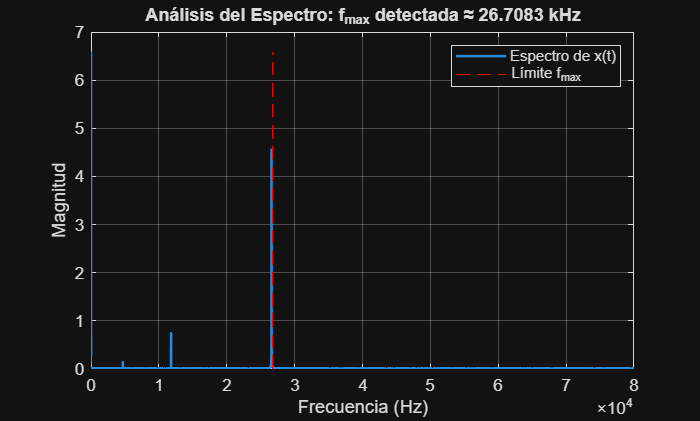

% 1. Calculamos la frecuencia de muestreo original de x
Ts = t(2) - t(1);
fs_original = 1/Ts;

% 2. Calculamos la FFT de la señal x
N = length(x);
X_fft = fft(x);
X_mag = abs(X_fft) / N; % Magnitud normalizada

% 3. Creamos el vector de frecuencias (de 0 a fs)
f = (0:N-1) * (fs_original / N);

% 4. Buscamos la frecuencia máxima (fmax) 
% Definimos un umbral (ej. el 1% de la magnitud del pico más alto)
umbral = 0.01 * max(X_mag);
indices_con_energia = find(X_mag(1:floor(N/2)) > umbral); 
f_max_detectada = f(indices_con_energia(end));

% 5. Representación gráfica para la defensa
figure('Name', 'Comprobación de Frecuencia Máxima');
plot(f(1:floor(N/2)), X_mag(1:floor(N/2)), 'LineWidth', 1.5);
hold on;
line([f_max_detectada f_max_detectada], [0 max(X_mag)], 'Color', 'r', 'LineStyle', '--');
grid on;
title(['Análisis del Espectro: f_{max} detectada ≈ ', num2str(f_max_detectada/1000), ' kHz']);
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');
legend('Espectro de x(t)', 'Límite f_{max}');

% Mostrar resultado por consola
fprintf('La frecuencia máxima detectada es: %.2f Hz\n', f_max_detectada);

La frecuencia máxima detectada es: 26708.33 Hz


fprintf('Por tanto, la fs_min (Nyquist) debe ser: %.2f Hz\n', 2 * f_max_detectada);

Por tanto, la fs_min (Nyquist) debe ser: 53416.66 Hz


c) Remuestreo de la señal (Señales g y h)

fs_min = 2*f_max_detectada;
fs_g = (3/2) * fs_min;
fs_h = (2/3) * fs_min;

% Generamos los nuevos vectores de tiempo
t_g = (t(1) : 1/fs_g : t(end)).';
t_h = (t(1) : 1/fs_h : t(end)).';

% Interpolación spline para obtener los nuevos valores
g = interp1(t, x, t_g, 'spline');
h = interp1(t, x, t_h, 'spline');

d) Representación del espectro en frecuencia

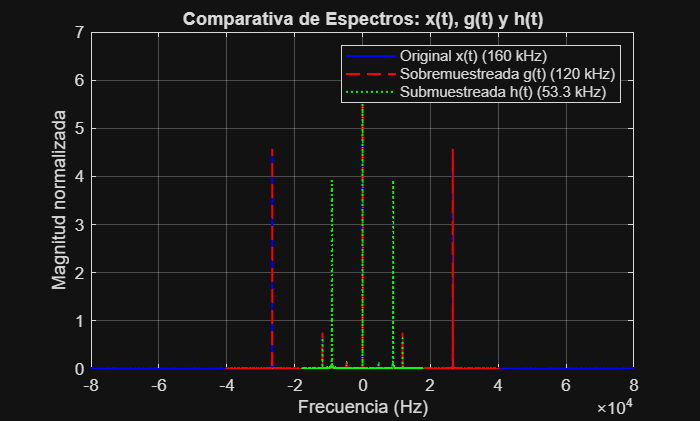

% Calculamos la FFT de cada señal y normalizamos por su longitud
X_f = fftshift(abs(fft(x)/length(x)));
G_f = fftshift(abs(fft(g)/length(g)));
H_f = fftshift(abs(fft(h)/length(h)));

% Generamos los ejes de frecuencia (cada uno depende de su propia fs)
f_x = linspace(-fs_x/2, fs_x/2, length(x));
f_g = linspace(-fs_g/2, fs_g/2, length(g));
f_h = linspace(-fs_h/2, fs_h/2, length(h));

% Representación comparativa
figure;
plot(f_x, X_f, 'b', 'LineWidth', 1.2); hold on;
plot(f_g, G_f, 'r--', 'LineWidth', 1.2);
plot(f_h, H_f, 'g:', 'LineWidth', 1.2);

grid on;
xlabel('Frecuencia (Hz)');
ylabel('Magnitud normalizada');
title('Comparativa de Espectros: x(t), g(t) y h(t)');
legend('Original x(t) (160 kHz)', 'Sobremuestreada g(t) (120 kHz)', 'Submuestreada h(t) (53.3 kHz)');

e) Representación en el dominio del tiempo

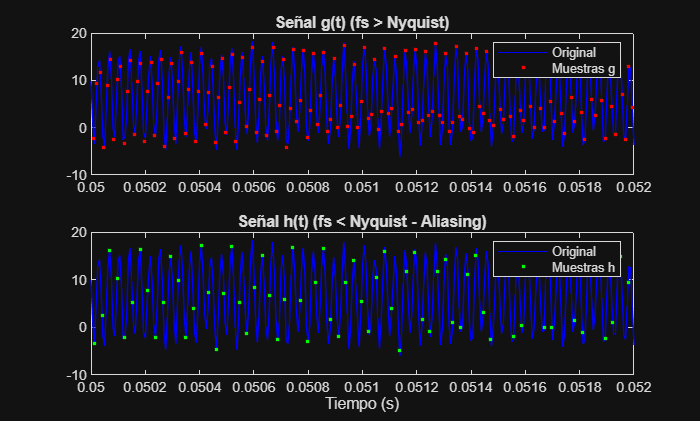

% Comparación temporal con zoom para apreciar las muestras
figure;
subplot(2,1,1);
plot(t, x, 'b'); hold on;
plot(t_g, g, 'r.'); 
title('Señal g(t) (fs > Nyquist)');
legend('Original', 'Muestras g');
xlim([0.05, 0.052]); % Zoom para ver los puntos

subplot(2,1,2);
plot(t, x, 'b'); hold on;
plot(t_h, h, 'g.');
title('Señal h(t) (fs < Nyquist - Aliasing)');
legend('Original', 'Muestras h');
xlim([0.05, 0.052]);
xlabel('Tiempo (s)');

## 2. CUANTIFICACIÓN UNIFORME

f) Cuantificación de k(t) con diferentes configuraciones

% Nota: B = 1 (signo) + bits_enteros + bits_decimales

% 1. 3 bits entera, 0 bits decimal: B = 1+3+0 = 4; D = 0
q30 = quantizer('fixed', 'round', 'saturate', [4, 0]);
k_s30 = bin2num(q30, num2bin(q30, k));

% 2. 1 bit entera, 2 bits decimal: B = 1+1+2 = 4; D = 2
q12 = quantizer('fixed', 'round', 'saturate', [4, 2]);
k_s12 = bin2num(q12, num2bin(q12, k));


% 3. 3 bits entera, 2 bits decimal: B = 1+3+2 = 6; D = 2
q32 = quantizer('fixed', 'round', 'saturate', [6, 2]);
k_s32 = bin2num(q32, num2bin(q32, k));

% 4. 5 bits entera, 0 bits decimal: B = 1+5+0 = 6; D = 0
q50 = quantizer('fixed', 'round', 'saturate', [6, 0]);
k_s50 = bin2num(q50, num2bin(q50, k));

g) Análisis en el dominio del tiempo y la frecuencia

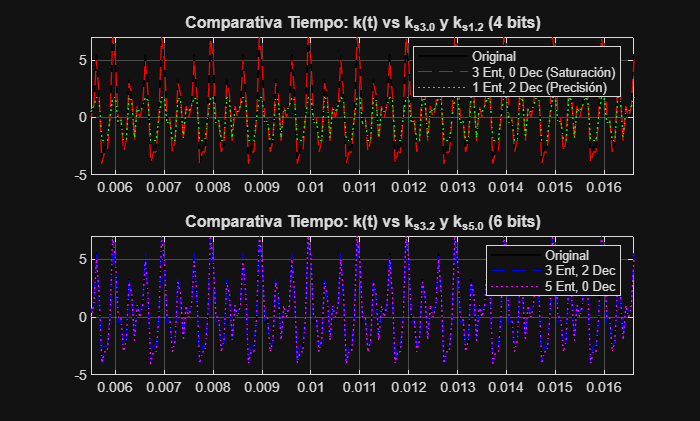

% --- ANÁLISIS TEMPORAL ---
figure('Name', 'Análisis Temporal Cuantificación');
subplot(2,1,1);
plot(t_k, k, 'k', 'LineWidth', 1); hold on;
plot(t_k, k_s30, 'r--'); 
plot(t_k, k_s12, 'g:');
title('Comparativa Tiempo: k(t) vs k_{s3.0} y k_{s1.2} (4 bits)');
legend('Original', '3 Ent, 0 Dec (Saturación)', '1 Ent, 2 Dec (Precisión)');
xlim([t_k(100) t_k(300)]); % Zoom para ver los escalones
grid on;

subplot(2,1,2);
plot(t_k, k, 'k', 'LineWidth', 1); hold on;
plot(t_k, k_s32, 'b--');
plot(t_k, k_s50, 'm:');
title('Comparativa Tiempo: k(t) vs k_{s3.2} y k_{s5.0} (6 bits)');
legend('Original', '3 Ent, 2 Dec', '5 Ent, 0 Dec');
xlim([t_k(100) t_k(300)]);
grid on;

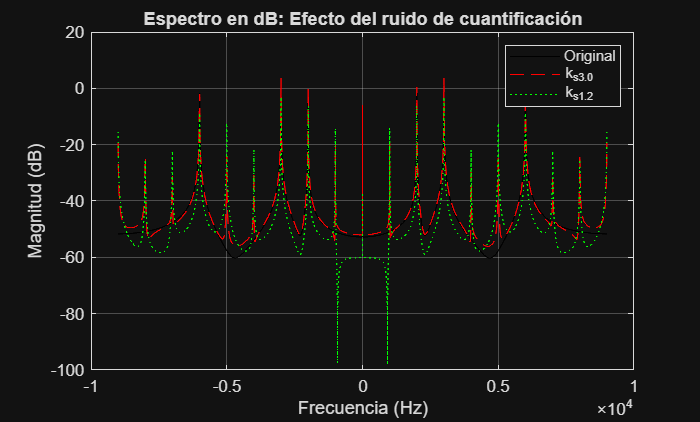


% --- ANÁLISIS FRECUENCIAL ---
fs_k = 1/(t_k(2)-t_k(1));
f_k = linspace(-fs_k/2, fs_k/2, length(k));

K_f = fftshift(abs(fft(k)/length(k)));
K30_f = fftshift(abs(fft(k_s30)/length(k_s30)));
K12_f = fftshift(abs(fft(k_s12)/length(k_s12)));

figure('Name', 'Análisis Frecuencial Cuantificación');
plot(f_k, 20*log10(K_f), 'k'); hold on;
plot(f_k, 20*log10(K30_f), 'r--');
plot(f_k, 20*log10(K12_f), 'g:');
title('Espectro en dB: Efecto del ruido de cuantificación');
legend('Original', 'k_{s3.0}', 'k_{s1.2}');
ylabel('Magnitud (dB)'); xlabel('Frecuencia (Hz)');
grid on;

h) Error Cuadrático Medio (ECM)

% Cálculo del ECM siguiendo la fórmula del PDF
ecm_s30 = mean((k - k_s30).^2);
ecm_s12 = mean((k - k_s12).^2);
ecm_s32 = mean((k - k_s32).^2);
ecm_s50 = mean((k - k_s50).^2);

fprintf('ECM para k_s3.0: %e\n', ecm_s30);

ECM para k_s3.0: 1.153129e-01


fprintf('ECM para k_s1.2: %e\n', ecm_s12);

ECM para k_s1.2: 2.966719e+00


fprintf('ECM para k_s3.2: %e\n', ecm_s32);

ECM para k_s3.2: 9.039844e-03


fprintf('ECM para k_s5.0: %e\n', ecm_s50);

ECM para k_s5.0: 1.153129e-01


## 3. AUDIO: CUANTIFICACIÓN Y ANÁLISIS

a) Preparación de la señal de audio (Eliminación de silencios)

% 1. Leer el archivo
nombre_archivo = 'PDS_P1_3A_LE2_G4.wav'; 

if exist(nombre_archivo, 'file')
    [x_audio, fs_audio] = audioread(nombre_archivo);
else
    error('ERROR: No se encuentra el archivo %s. Verifica la carpeta.', nombre_archivo);
end

% 2. Eliminar silencios anteriores y posteriores (|x| < 0.01 V)
umbral = 0.01;
indices = find(abs(x_audio) >= umbral); % Busca dónde hay sonido
y_audio = x_audio(indices(1):indices(end)); % Recorta desde el primer sonido al último

% 3. Cuantificador de 7 bits (B=7)
% RAZONAMIENTO: 
% Las señales de audio suelen estar normalizadas entre -1 y 1. 
% Un cuantificador 'fixed' con B=7 usa 1 bit para el signo.
% Si asignamos D=6 bits decimales, el rango es [-1, 0.984]. Es la máxima resolución posible.
% Si asignamos D=5 bits decimales, el rango es [-2, 1.968]. Menos resolución pero evitamos saturar si hay picos en 1.
% ELEGIMOS: B=7, D=6 para priorizar la resolución en una señal normalizada.

B_audio = 7;
D_audio = 6;
q_audio = quantizer('fixed', 'round', 'saturate', [B_audio, D_audio]);
y_cuant = bin2num(q_audio, num2bin(q_audio, y_audio));

% 4. Reproducción (Descomenta para escuchar)
% disp('Escuchando original...'); sound(y_audio, fs_audio);
% pause(length(y_audio)/fs_audio + 1);
% disp('Escuchando cuantificada...'); sound(y_cuant, fs_audio);

## 4. ANÁLISIS DE RESULTADOS

a) Reproducción para comparativa cualitativa

% 1. Definir la frecuencia de muestreo (asegúrate de haberla obtenido con audioread)
% fs_audio es la que devuelve [x, fs_audio] = audioread(...)

fprintf('Reproduciendo señal ORIGINAL (sin silencios)...\n');

Reproduciendo señal ORIGINAL (sin silencios)...


sound(y_audio, fs_audio); 

% Es necesario pausar el código mientras suena el audio 
% para que no empiece el siguiente inmediatamente.
pause(length(y_audio)/fs_audio + 1); 

fprintf('Reproduciendo señal CUANTIFICADA (7 bits)...\n');

Reproduciendo señal CUANTIFICADA (7 bits)...


sound(y_cuant, fs_audio);

b) Representación temporal con marcadores

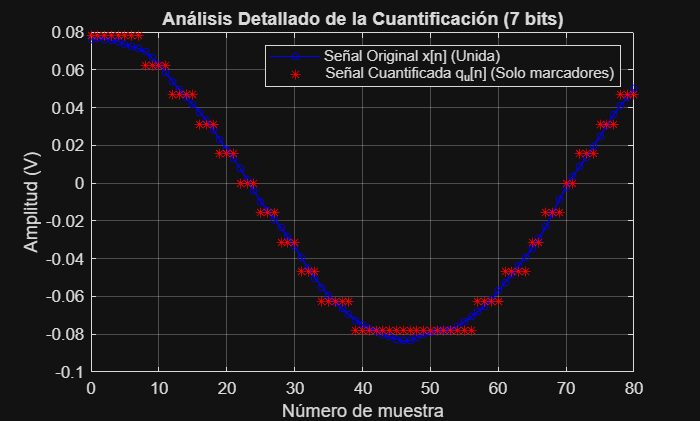

% Seleccionamos un segmento corto para que se vean bien los puntos (ej. 100 muestras)
segmento = 1000:1080; 
t_segmento = (0:length(segmento)-1); % Eje de muestras

figure('Name', 'Análisis de Resultados: Marcadores');
% Señal original: Unida con línea y con marcador de círculo
plot(t_segmento, y_audio(segmento), 'b-o', 'MarkerSize', 4); hold on;

% Señal cuantificada: SOLO el marcador (asterisco rojo), sin línea
plot(t_segmento, y_cuant(segmento), 'r*', 'MarkerSize', 6);

title('Análisis Detallado de la Cuantificación (7 bits)');
xlabel('Número de muestra');
ylabel('Amplitud (V)');
legend('Señal Original x[n] (Unida)', 'Señal Cuantificada q_u[n] (Solo marcadores)');
grid on;

c) Comparativa cuantitativa (ECM)

% Cálculo del Error Cuadrático Medio
N_audio = length(y_audio);
ecm_audio = (1/N_audio) * sum((y_audio - y_cuant).^2);

fprintf('El Error Cuadrático Medio (ECM) del audio es: %e\n', ecm_audio);

El Error Cuadrático Medio (ECM) del audio es: 2.031533e-05
